2. .* & *

A = [1,2,3;4,5,6;7,8,9];
B = [2,2,2;2,2,2;2,2,2];
disp(A*B);

    12    12    12
    30    30    30
    48    48    48



disp(A.*B);

     2     4     6
     8    10    12
    14    16    18



3.Data Slice

A = [1,2,3;4,5,6;7,8,9];
first_row = A(1,:);
first_col = A(:,1);
exclude_first_rowcol = A(2:3,2:3);

disp(A);

     1     2     3
     4     5     6
     7     8     9



disp(first_row);

     1     2     3



disp(first_col);

     1
     4
     7



disp(exclude_first_rowcol);

     5     6
     8     9



4.Loops--for loop & while loop

for i = 1:5
    disp(i);
end

     1

     2

     3

     4

     5




n = 1;
while n <=5
    disp(n);
    n=n+1;
end

     1

     2

     3

     4

     5



5.Functions

func1(1,1);

6.plot

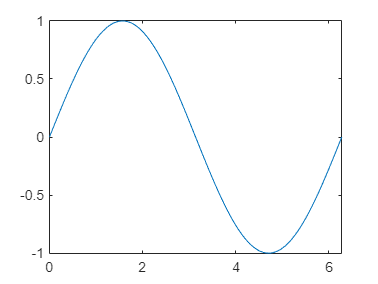

x = linspace(0,2*pi,100);
y = sin(x);
plot(x,y);

7.Simple Exercise

Ex1:Write a simple func that returns the volume of a cone.The inputs to the function are radius and height(in meters)

7.1.disp(FindVolumeOfCone(10,20));

x = FindVolumeOfCone(2,11);
disp(x);

   46.0767



test = fprintf("%0.2f",x);

46.08

disp(test);

     5



7.2.Modify the func so that the inputs radius and height are now an arrary

inputRadius = [0,1,3.3,4,5];
inputHeights = [12,12,12,12,12];

x = FindVolumeOfCone2(inputRadius,inputHeights);
disp(x);

         0   12.5664  136.8478  201.0619  314.1593



test = fprintf("%0.2f",x);

0.0012.57136.85201.06314.16

disp(test);

    27



7.3Plot volumes versus radii

Label the xaxis 'Radius' and the y-axix "Volume"

Use a fontsize of 20 for your axis labels.Use a red line in your plot with a thickness of 3 units.

Inicate every data point wiht (*)

Date:2023 09 19

Description: ADD Area calculation function depends on calCneVolumeArea

inputRadius = [0,1,3.3,4,5];
inputHeights = [12,12,12,12,12];
lengths = [5,5,5,5,5];

x = FindVolumeOfCone2(inputRadius,inputHeights);
[Cone_volume, Cone_area] = calcConeVolumeArea(inputRadius,inputHeights,lengths);

disp(x);

         0   12.5664  136.8478  201.0619  314.1593



test = fprintf("%0.2f",x);

0.0012.57136.85201.06314.16

disp(test);

    27



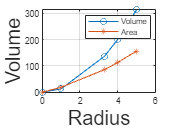


%plot(inputRadius,x,"r","LineWidth",3);
plot(inputRadius,x,'o-',inputRadius,Cone_area,'-*')

ylabel("Volume","FontSize",20);
xlabel("Radius","FontSize",20);
legend("Volume","Area");
grid on;

function def

when it comes to the matrix multiple

"." is needed !

function [output1,output2] = func1(a,b)
    output1 = a*b;
    output2 = a.*b;
end

function [volume] = FindVolumeOfCone(radius,height)
    volume = 1/3 * pi * (radius.^2) * height;
end

function [volume] = FindVolumeOfCone2(radius,height)
    volume = 1./3 .* pi .* (radius.^2) .* height;
end